# Experiment 2: Using imagePretrainedNetwork (ResNet50) on Whole Image

## Clean environment

close all;
clear variables;
clc;
rng(42);

## Set folder path

folder = "C:\Users\u3253992\workspace\computer-vision\assignment_1\u3253992_assgn_1_best\CUB_200_2011\";

## Load dataset

[trainingImageNames, validationImageNames, testImageNames, classNames, imageClassLabels] = loadDataset(folder);

No bounding Box


numClasses = height(classNames);

## Create datastores

disp('Training set class distribution:');

Training set class distribution:


trainingImageDS = createImageDatastore(trainingImageNames, folder);

    Label    Count
    _____    _____

     001      36  
     002      36  
     003      35  
     004      36  
     005      26  
     006      25  
     007      30  
     008      29  
     009      35  
     010      36  
     011      36  
     012      34  
     013      36  
     014      36  
     015      35  
     016      35  
     017      34  
     018      26  
     019      35  
     020      35  
     021      36  
     022      34  
     023      35  
     024      31  
     025      36  
     026      36  
     027      36  
     028      35  
     029      36  
     030      36  
     031      36  
     032      32  
     033      35  
     034      35  
     035      36  
     036      36  
     037      35  
     038      36  
     039      35  
     040      36  
     041      36  
     042      36  
     043      35  
     044      36  
     045      36  
     046      36  
     047      36  



disp('Validation set class distribution:');

Validation set class distribution:


validationImageDS = createImageDatastore(validationImageNames, folder);

    Label    Count
    _____    _____

     001      12  
     002      12  
     003      12  
     004      12  
     005       9  
     006       8  
     007      12  
     008      10  
     009      12  
     010      12  
     011      12  
     012      11  
     013      12  
     014      12  
     015      12  
     016      12  
     017      12  
     018      10  
     019      12  
     020      12  
     021      12  
     022      11  
     023      12  
     024      11  
     025      12  
     026      12  
     027      12  
     028      12  
     029      12  
     030      12  
     031      12  
     032      11  
     033      12  
     034      12  
     035      12  
     036      12  
     037      12  
     038      12  
     039      12  
     040      12  
     041      12  
     042      12  
     043      12  
     044      12  
     045      12  
     046      12  
     047      12  



disp('Test set class distribution:');

Test set class distribution:


testImageDS = createImageDatastore(testImageNames, folder);

    Label    Count
    _____    _____

     001      12  
     002      12  
     003      11  
     004      12  
     005       9  
     006       8  
     007      12  
     008       9  
     009      12  
     010      12  
     011      12  
     012      11  
     013      12  
     014      12  
     015      11  
     016      11  
     017      11  
     018       9  
     019      12  
     020      12  
     021      12  
     022      11  
     023      12  
     024      10  
     025      12  
     026      12  
     027      12  
     028      12  
     029      12  
     030      12  
     031      12  
     032      10  
     033      12  
     034      12  
     035      12  
     036      12  
     037      12  
     038      12  
     039      12  
     040      12  
     041      12  
     042      12  
     043      12  
     044      12  
     045      12  
     046      12  
     047      12  


## Load pretrained ResNet-50

net       = resnet50; % requires Deep Learning Toolbox Model for ResNet-50
inputSize = net.Layers(1).InputSize;

## Resize image datastores and combine them with the labels

targetSize = inputSize(1:2);
trainCDS = resizeCombineDatastore(trainingImageDS, targetSize);
valCDS = resizeCombineDatastore(validationImageDS, targetSize);
testCDS = resizeCombineDatastore(testImageDS, targetSize);

## Show example images

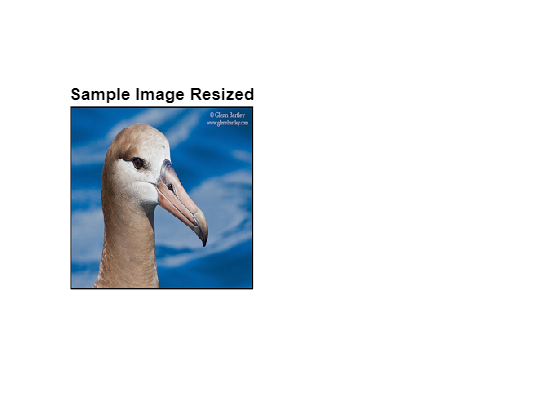

showImage(trainCDS)

## Enables GPU

[device, useGPU] = enableGPU();

✅ GPU found and ready:
  CUDADevice with properties:

                 Name: 'NVIDIA GeForce RTX 3070'
                Index: 1 (of 1)
    ComputeCapability: '8.6'
          DriverModel: 'WDDM'
          TotalMemory: 8589410304 (8.59 GB)
      AvailableMemory: 7439773696 (7.44 GB)
      DeviceAvailable: true
       DeviceSelected: true

  Show 

## Build the layer graph and swap out the last 3 layers

lgraph = layerGraph(net);

% 1) New fully‐connected layer (20 classes)
newFc = fullyConnectedLayer(numClasses, ...
    'Name','fc20', ...
    'WeightLearnRateFactor',10, ...
    'BiasLearnRateFactor',10);

% 2) New softmax
newSoftmax = softmaxLayer('Name','softmax20');

% 3) New classification output
newClassOutput = classificationLayer('Name','classoutput20');

% Replace them
lgraph = replaceLayer(lgraph, 'fc1000', newFc);
lgraph = replaceLayer(lgraph, 'fc1000_softmax', newSoftmax);
lgraph = replaceLayer(lgraph, 'ClassificationLayer_fc1000', newClassOutput);

## Training options

options = trainingOptions('adam', ...
    'MiniBatchSize',32, ...
    'MaxEpochs',7, ...
    'InitialLearnRate',1e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',valCDS, ...
    'ValidationFrequency',floor(numel(trainingImageDS.Files)/32), ...
    'Verbose',true, ...
    'Plots','training-progress', ...
    'ExecutionEnvironment','gpu');

## Train the network

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:52 |        0.00% |        0.89% |       5.6059 |       5.9081 |      1.0000e-04 |
|       1 |          50 |       00:01:20 |       18.75% |              |       3.4978 |              |      1.0000e-04 |
|       1 |         100 |       00:01:49 |       37.50% |              |       2.5864 |              |      1.0000e-04 |
|       1 |         150 |       00:02:18 |       56.25% |              |       1.7722 |              |      1.0000

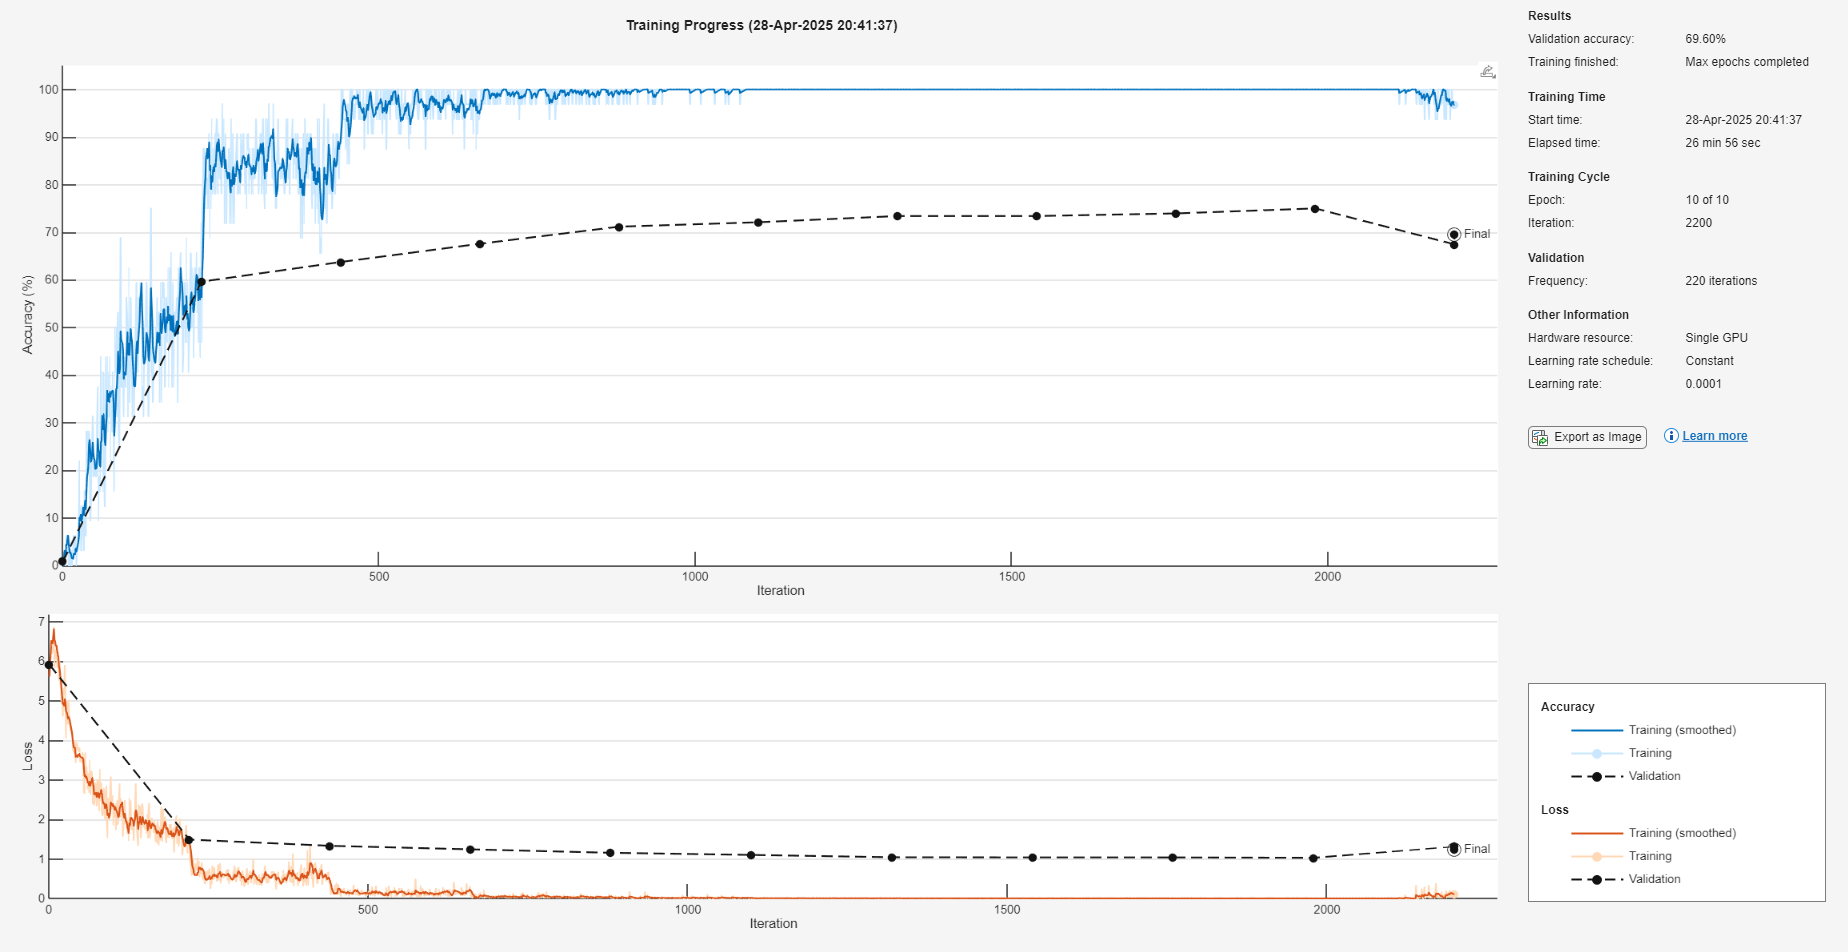

% trainedNet = trainnet(trainCDS, net, "crossentropy", options);
resnet20 = trainNetwork(trainCDS, lgraph, options);

## Evaluate the model

% scoresTest = minibatchpredict(trainedNet, testCDS)
% pred = scores2label(scoresTest,classNames.className);
% [~, yPred] = max(scoresTest, [], 2);
% % disp("Predictions");
% % disp(yPred);
% yTest = str2double(string(testImageDS.Labels))
% accuracy = sum(yPred == yTest) / numel(yTest);
% disp(accuracy)

[trainAcc, ~]   = evaluateClassifier(resnet20, trainCDS,   trainingImageDS.Labels,   true);
[valAcc,   ~]   = evaluateClassifier(resnet20, valCDS,     validationImageDS.Labels, true);
[testAcc, preds] = evaluateClassifier(resnet20, testCDS,   testImageDS.Labels,       true);

fprintf("Train Accuracy = %.1f%%\n", trainAcc*100);

Train Accuracy = 99.3%


fprintf("Val   Accuracy = %.1f%%\n", valAcc*100);

Val   Accuracy = 69.6%


fprintf("Test  Accuracy = %.1f%%\n", testAcc*100);

Test  Accuracy = 67.5%


## Plot confusion matrix

% plotConfusionMatrix(yTest, yPred, "Exp.2 ResNet-18 Overall Accuracy: " + string(round(accuracy*100, 1)) + "%");

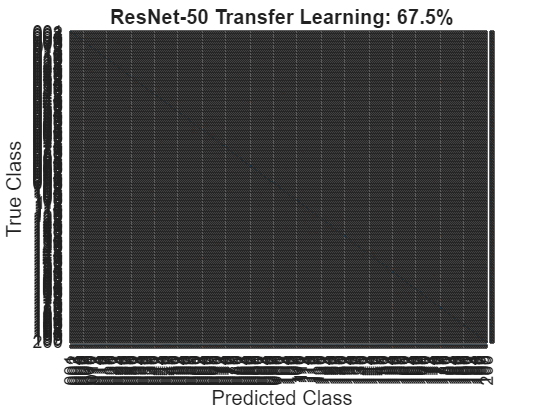

Classwise Recognition Rates:
   83.3000
   75.0000
   72.7000
   58.3000
   77.8000
   75.0000
   66.7000
   33.3000
   66.7000
  100.0000
   41.7000
   54.5000
   91.7000
   66.7000
   81.8000
   54.5000
   72.7000
  100.0000
   58.3000
   83.3000
   83.3000
   81.8000
   41.7000
   90.0000
   75.0000
   25.0000
   50.0000
   91.7000
   50.0000
   25.0000
   66.7000
   40.0000
   25.0000
   75.0000
   83.3000
   91.7000
   58.3000
   75.0000
   58.3000
   58.3000
   66.7000
   91.7000
   41.7000
   83.3000
   66.7000
   58.3000
   75.0000
   91.7000
   66.7000
   58.3000
   83.3000
  100.0000
   91.7000
   66.7000
   41.7000
   16.7000
   83.3000
   81.8000
   33.3000
   41.7000
   91.7000
   25.0000
  100.0000
   25.0000
   50.0000
   58.3000
   33.3000
   83.3000
   83.3000
  100.0000
   25.0000
   50.0000
   91.7000
  100.0000
   90.9000
   75.0000
   75.0000
   50.0000
   58.3000
   66.7000
   75.0000
   66.7000
  100.0000
   75.0000
   83.3000
   75.0000
   91.7000
   91.7000
   

plotConfusionMatrix(testImageDS.Labels, preds, ...
    sprintf("ResNet-50 Transfer Learning: %.1f%%", testAcc*100));